VideoWriter

sample = VideoWriter(fullfile('sample.avi'));
sample.FrameRate = 142;
open(sample)

image file

imageNames = dir(fullfile('/home/honda/data/OTB/Biker','img','*.jpg'));
imageNames = {imageNames.name}';

writing

for ii = 1:length(imageNames)
    img = imread(fullfile('/home/honda/data/OTB/Biker','img',imageNames{ii}));
    writeVideo(sample,img)
end

close(sample)

avi = VideoReader(fullfile('sample.avi'));


ii = 1;
while hasFrame(avi)
    mov(ii) = im2frame(readFrame(avi));
    ii=ii+1;
end

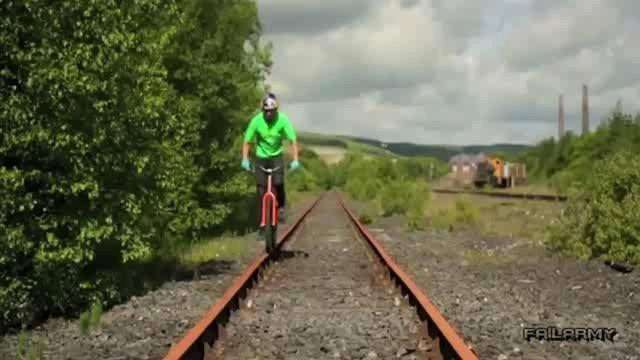

figure 
imshow(mov(1).cdata, 'Border', 'tight')
movie(mov,1,142)

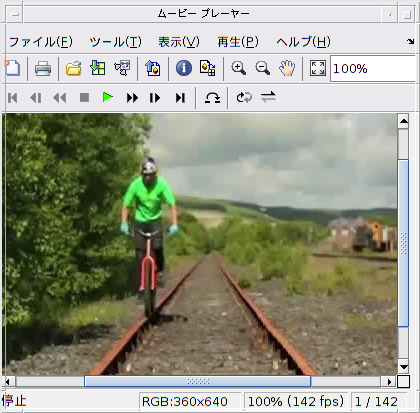

implay('sample.avi')